Data file name

clear; clc;
dataFileName = 'tial_7.txt';
if ~isfile(dataFileName)
    error('File %s not found in the current directory.', dataFileName);
end
fileID = fopen(dataFileName, 'r');
% Skip the first 5 lines (header information)
for i = 1:5
    fgetl(fileID);
end
% Read the data columns
% Format: Time(s) | V_P2(V) | V_Q(V) | P2(MPa) | Q(L/min) | Safety
data = textscan(fileID, '%f %f %f %f %f %s');
fclose(fileID);
% Extract the variables globally for plotting
time_s  = data{1};
V_P2    = data{2};
V_Q     = data{3};
P2_MPa  = data{4};
Q_L_min = data{5};
if isempty(time_s)
    error('No data found in %s.', dataFileName);
end
disp('Data successfully extracted and ready for plotting.');

Data successfully extracted and ready for plotting.


plot saved data

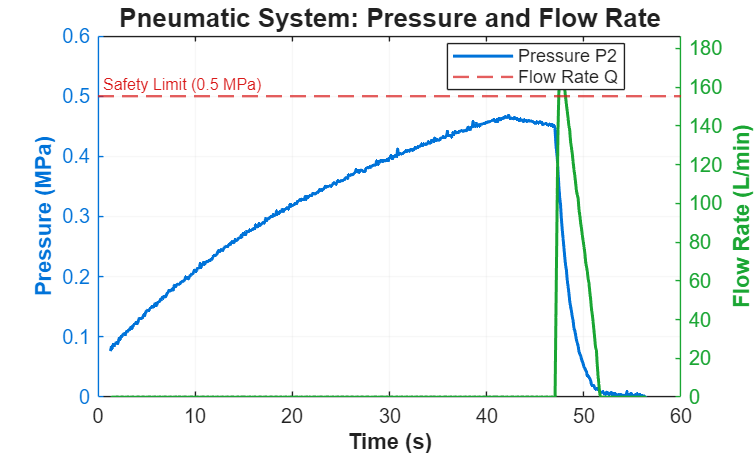

% 4. Create the dual-axis plot
figure('Name', 'Saved Pneumatic Data', 'NumberTitle', 'off', 'Color', 'white');

% Enable left y-axis for Pressure
yyaxis left;
plot(time_s, P2_MPa, '-', 'Color', [0.0 0.45 0.85], 'LineWidth', 1.5);
ylabel('Pressure (MPa)', 'FontWeight', 'bold');
% Set left y-axis limits to start at 0, and add a little padding on top
ylim([0, max([0.6, max(P2_MPa) * 1.1])]);
% Add safety limit line
yline(0.5, '--', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.2, 'Label', 'Safety Limit (0.5 MPa)', 'LabelHorizontalAlignment', 'left', 'FontSize', 8);
set(gca, 'YColor', [0.0 0.45 0.85]); % Match axis color to line color

% Enable right y-axis for Flow Rate
yyaxis right;
plot(time_s, Q_L_min, '-', 'Color', [0.1 0.65 0.2], 'LineWidth', 1.5);
ylabel('Flow Rate (L/min)', 'FontWeight', 'bold');
% Set right y-axis limits to start at 0
ylim([0, max([10, max(Q_L_min) * 1.1])]);
set(gca, 'YColor', [0.1 0.65 0.2]); % Match axis color to line color

% X-axis and general plot settings
xlabel('Time (s)', 'FontWeight', 'bold');
title('Pneumatic System: Pressure and Flow Rate', 'FontSize', 13, 'FontWeight', 'bold');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);

% Add a legend
legend({'Pressure P2', 'Flow Rate Q'}, 'Location', 'best');

see all datasets in one experiment

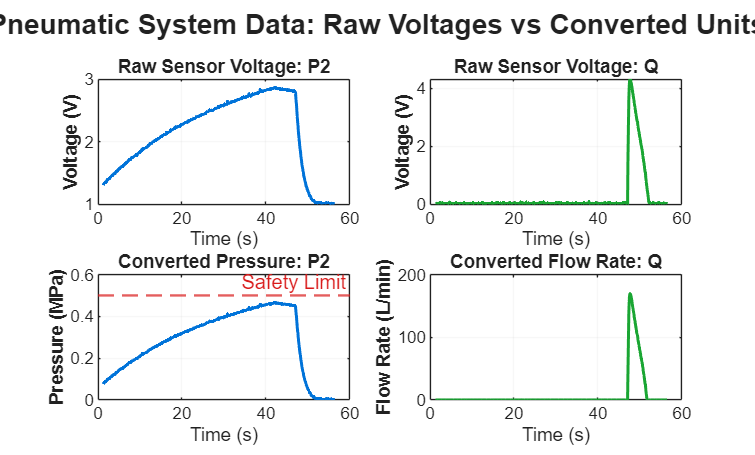


% 4. Create a figure with 4 subplots
figure('Name', 'Saved Pneumatic Data - 4 Subplots', 'NumberTitle', 'off', 'Color', 'white');

% --- Subplot 1: V_P2 (Voltage) ---
subplot(2, 2, 1);
plot(time_s, V_P2, '-', 'Color', [0.0 0.45 0.85], 'LineWidth', 1.5);
ylabel('Voltage (V)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Raw Sensor Voltage: P2');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);

% --- Subplot 2: V_Q (Voltage) ---
subplot(2, 2, 2);
plot(time_s, V_Q, '-', 'Color', [0.1 0.65 0.2], 'LineWidth', 1.5);
ylabel('Voltage (V)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Raw Sensor Voltage: Q');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);

% --- Subplot 3: P2 (Pressure) ---
subplot(2, 2, 3);
plot(time_s, P2_MPa, '-', 'Color', [0.0 0.45 0.85], 'LineWidth', 1.5);
hold on;
yline(0.5, '--', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.2, 'Label', 'Safety Limit');
hold off;
ylabel('Pressure (MPa)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Converted Pressure: P2');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);
ylim([0, max([0.6, max(P2_MPa) * 1.1])]);

% --- Subplot 4: Q (Flow Rate) ---
subplot(2, 2, 4);
plot(time_s, Q_L_min, '-', 'Color', [0.1 0.65 0.2], 'LineWidth', 1.5);
ylabel('Flow Rate (L/min)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Converted Flow Rate: Q');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);

% Overall Title
sgtitle('Pneumatic System Data: Raw Voltages vs Converted Units', 'FontSize', 14, 'FontWeight', 'bold');

sss

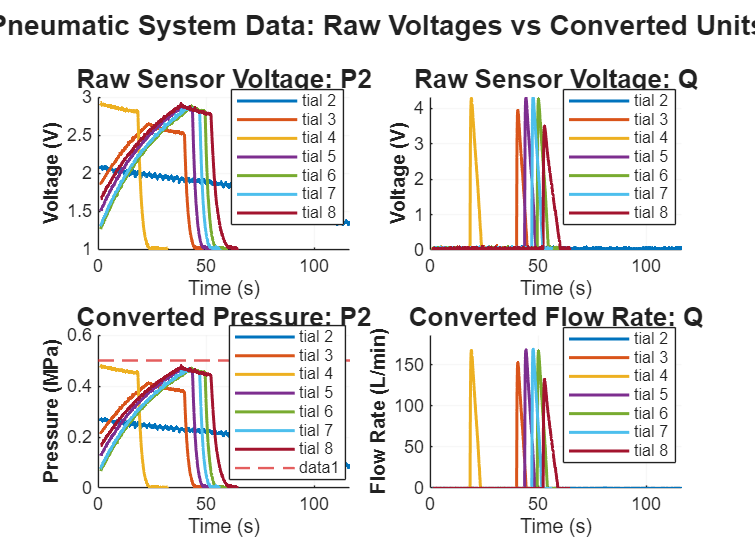

% MATLAB Script comparing trials 2 to 8 - Visual Style adapted from postprecessing.mlx
clear; clc; close all;

% 1. Define the 7 trial files to compare (tial_2 to tial_8)
trialFiles = {
    'tial_2.txt', ...
    'tial_3.txt', ...
    'tial_4.txt', ...
    'tial_5.txt', ...
    'tial_6.txt', ...
    'tial_7.txt', ...
    'tial_8.txt'
};

% Curated 7-color palette to clearly distinguish the runs
colors = {
    [0.00, 0.45, 0.74], ... % Trial 2: Slate Blue
    [0.85, 0.33, 0.10], ... % Trial 3: Coral Orange
    [0.93, 0.69, 0.13], ... % Trial 4: Golden Yellow
    [0.49, 0.18, 0.56], ... % Trial 5: Muted Purple
    [0.47, 0.67, 0.19], ... % Trial 6: Olive Green
    [0.30, 0.75, 0.93], ... % Trial 7: Light Blue/Cyan
    [0.64, 0.08, 0.18]      % Trial 8: Burgundy Red
};

% 2. Load and parse the data for each file
numTrials = length(trialFiles);
datasets = cell(1, numTrials);

for i = 1:numTrials
    fileName = trialFiles{i};
    
    % Resolve path dynamically (works from project root or validation folder)
    if isfile(fileName)
        filePath = fileName;
    elseif isfile(fullfile('validation', fileName))
        filePath = fullfile('validation', fileName);
    else
        error('File "%s" not found in the current directory or validation/ folder.', fileName);
    end
    
    % Read text file
    fileID = fopen(filePath, 'r');
    if fileID == -1
        error('Could not open file: %s', filePath);
    end
    
    % Skip the first 5 lines (header information)
    for h = 1:5
        fgetl(fileID);
    end
    
    % Read columns: Time(s) | V_P2(V) | V_Q(V) | P2(MPa) | Q(L/min) | Safety
    parsedData = textscan(fileID, '%f %f %f %f %f %s');
    fclose(fileID);
    
    % Store in structure for easy plotting
    datasets{i}.name    = strrep(fileName, '.txt', '');
    datasets{i}.time    = parsedData{1};
    datasets{i}.V_P2    = parsedData{2};
    datasets{i}.V_Q     = parsedData{3};
    datasets{i}.P2      = parsedData{4};
    datasets{i}.Q       = parsedData{5};
end

% 3. Create the comparison figure with a white background
figure('Name', 'Saved Pneumatic Data - 7 Trials Comparison', ...
       'NumberTitle', 'off', ...
       'Color', 'white', ...
       'Position', [100, 100, 1100, 800]);

% Determine global limits for scaling the Y-axes matching the mlx style formulas
all_P2 = [];
all_Q = [];
for i = 1:numTrials
    all_P2 = [all_P2; datasets{i}.P2];
    all_Q = [all_Q; datasets{i}.Q];
end
max_P2_limit = max([0.6, max(all_P2) * 1.1]);
max_Q_limit  = max([10, max(all_Q) * 1.1]);

% 4. Generate the subplots

% --- Subplot 1: V_P2 (Voltage) ---
subplot(2, 2, 1);
hold on;
for i = 1:numTrials
    plot(datasets{i}.time, datasets{i}.V_P2, '-', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', strrep(datasets{i}.name, '_', ' '));
end
ylabel('Voltage (V)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Raw Sensor Voltage: P2', 'FontSize', 13, 'FontWeight', 'bold');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);
legend('show', 'Location', 'best');
hold off;

% --- Subplot 2: V_Q (Voltage) ---
subplot(2, 2, 2);
hold on;
for i = 1:numTrials
    plot(datasets{i}.time, datasets{i}.V_Q, '-', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', strrep(datasets{i}.name, '_', ' '));
end
ylabel('Voltage (V)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Raw Sensor Voltage: Q', 'FontSize', 13, 'FontWeight', 'bold');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);
legend('show', 'Location', 'best');
hold off;

% --- Subplot 3: P2 (Pressure) ---
subplot(2, 2, 3);
hold on;
for i = 1:numTrials
    plot(datasets{i}.time, datasets{i}.P2, '-', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', strrep(datasets{i}.name, '_', ' '));
end
% Safety limit line using the exact style from the live script
yline(0.5, '--', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.2, 'Label', 'Safety Limit');
ylabel('Pressure (MPa)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Converted Pressure: P2', 'FontSize', 13, 'FontWeight', 'bold');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);
ylim([0, max_P2_limit]);
legend('show', 'Location', 'best');
hold off;

% --- Subplot 4: Q (Flow Rate) ---
subplot(2, 2, 4);
hold on;
for i = 1:numTrials
    plot(datasets{i}.time, datasets{i}.Q, '-', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', strrep(datasets{i}.name, '_', ' '));
end
ylabel('Flow Rate (L/min)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Converted Flow Rate: Q', 'FontSize', 13, 'FontWeight', 'bold');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);
ylim([0, max_Q_limit]);
legend('show', 'Location', 'best');
hold off;

% Overall Title matching the mlx styling
sgtitle('Pneumatic System Data: Raw Voltages vs Converted Units', ...
        'FontSize', 14, 'FontWeight', 'bold');

asked by seb

%% Pneumatic Discharge Analysis: Trials 5–8
%  Produces three figures matching the team visual style:
%    1. Average Measured Pressure vs Theoretical Pressure
%    2. Average Measured Flow Rate vs Theoretical Flow Rate
%    3. Residual (Theoretical − Measured Pressure)
clear; clc; close all;

%% 1. Configuration
fileList = {'tial_5.txt', 'tial_6.txt', 'tial_7.txt', 'tial_8.txt'};
numTrials = length(fileList);

% Physical parameters (adjust tau to best-fit your data)
P_atm = 0.1013;   % Atmospheric pressure (MPa) — where pressure decays to
tau   = 2.5;       % System discharge time constant (seconds) — tune this

%% 2. Load data and isolate the discharge phase
rawCells = cell(1, numTrials);
for k = 1:numTrials
    fid = fopen(fileList{k}, 'r');
    for skip = 1:5, fgetl(fid); end          % skip header
    D = textscan(fid, '%f %f %f %f %f %s');   % read all columns
    fclose(fid);

    time_raw = D{1};
    P2_raw   = D{4};   % Pressure in MPa
    Q_raw    = D{5};    % Flow rate in L/min

    % --- Detect valve-open instant: first sample with Q > 5 L/min ---
    valveIdx = find(Q_raw > 5, 1, 'first');
    if isempty(valveIdx)
        error('No discharge detected in %s', fileList{k});
    end

    % Extract from one sample *before* valve-open to end of file
    startIdx = max(1, valveIdx - 1);
    t_crop = time_raw(startIdx:end) - time_raw(startIdx);
    P_crop = P2_raw(startIdx:end);
    Q_crop = Q_raw(startIdx:end);

    rawCells{k} = [t_crop, P_crop, Q_crop];
end

%% 3. Interpolate all trials onto a common time grid
% Determine the shortest trial duration so we don't extrapolate
minDuration = min(cellfun(@(c) c(end,1), rawCells));
dt = 0.01;                              % 10 ms resolution
tCommon = (0:dt:minDuration)';

P_interp = zeros(length(tCommon), numTrials);
Q_interp = zeros(length(tCommon), numTrials);

for k = 1:numTrials
    P_interp(:, k) = interp1(rawCells{k}(:,1), rawCells{k}(:,2), tCommon, 'linear', 'extrap');
    Q_interp(:, k) = interp1(rawCells{k}(:,1), rawCells{k}(:,3), tCommon, 'linear', 'extrap');
end

% Mean and standard deviation across the 4 trials
meanP = mean(P_interp, 2);
stdP  = std(P_interp, 0, 2);
meanQ = mean(Q_interp, 2);
stdQ  = std(Q_interp, 0, 2);

%% 4. Build theoretical curves — auto-fit tau
P_atm = 0;          % Sensor reads gauge pressure (decays to 0, not 0.1013 MPa)
P_max = meanP(1);   % Initial pressure at valve open
Q_max = max(meanQ); % Peak flow rate

% --- Fit tau to minimise residual between theory and mean measured pressure ---
% Only fit over the region where pressure is meaningfully above noise
fitMask = meanP > 0.01;   % ignore near-zero tail (noisy)

tau_fit = fminsearch(@(tau) ...
    sum((meanP(fitMask) - (P_atm + (P_max - P_atm) * exp(-tCommon(fitMask) / tau))).^2), ...
    1.5);   % initial guess: 1.5 s

fprintf('Best-fit tau = %.4f s\n', tau_fit);

Best-fit tau = 1.6495 s


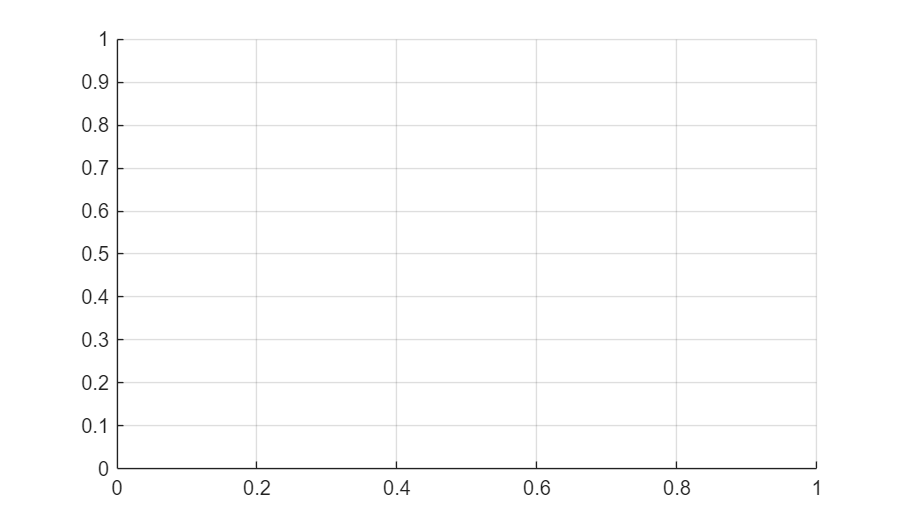


% Build curves with fitted tau
tau = tau_fit;
P_theo = P_atm + (P_max - P_atm) * exp(-tCommon / tau);
Q_theo = Q_max * exp(-tCommon / tau);

%% ===== FIGURE 1: Pressure over Time ====================================
figure('Name', 'Pressure: Measured vs Theory', ...
       'NumberTitle', 'off', 'Color', 'white', ...
       'Position', [100 400 720 420]);
hold on; grid on;


% Measured average ± SD (solid, with error bars)
hExp = errorbar(tCommon(1:dec:end), meanP(1:dec:end), stdP(1:dec:end), ...
    'o-', 'Color', [0.0 0.45 0.85], 'MarkerFaceColor', [0.0 0.45 0.85], ...
    'MarkerSize', 4, 'LineWidth', 1.3, 'CapSize', 4);

dec requires Fixed-Point Designer.


% Theoretical curve (dashed)
hTheo = plot(tCommon, P_theo, '--', 'Color', [0.85 0.1 0.1], 'LineWidth', 2);

xlabel('Time (s)', 'FontWeight', 'bold');
ylabel('Pressure (MPa)', 'FontWeight', 'bold');
title('Discharge Pressure: Measured vs Theoretical', ...
      'FontSize', 13, 'FontWeight', 'bold');
legend([hExp, hTheo], ...
    {'Mean Measured P \pm \sigma', ...
     'P(t) = P_{atm} + (P_{max} - P_{atm}) e^{-t/\tau}'}, ...
    'Location', 'northeast', 'FontSize', 9);
set(gca, 'GridColor', [0.8 0.8 0.8]);
hold off;

%% ===== FIGURE 2: Volumetric Flow Rate over Time ========================
figure('Name', 'Flow Rate: Measured vs Theory', ...
       'NumberTitle', 'off', 'Color', 'white', ...
       'Position', [100 400 720 420]);
hold on; grid on;

% Measured average ± SD (solid, with error bars)
hExpQ = errorbar(tCommon(1:dec:end), meanQ(1:dec:end), stdQ(1:dec:end), ...
    's-', 'Color', [0.1 0.65 0.2], 'MarkerFaceColor', [0.1 0.65 0.2], ...
    'MarkerSize', 4, 'LineWidth', 1.3, 'CapSize', 4);

% Theoretical curve (dashed)
hTheoQ = plot(tCommon, Q_theo, '--', 'Color', [0.85 0.1 0.1], 'LineWidth', 2);

xlabel('Time (s)', 'FontWeight', 'bold');
ylabel('Flow Rate (L/min)', 'FontWeight', 'bold');
title('Discharge Flow Rate: Measured vs Theoretical', ...
      'FontSize', 13, 'FontWeight', 'bold');
legend([hExpQ, hTheoQ], ...
    {'Mean Measured Q \pm \sigma', ...
     'Q(t) = Q_{max} e^{-t/\tau}'}, ...
    'Location', 'northeast', 'FontSize', 9);
set(gca, 'GridColor', [0.8 0.8 0.8]);
hold off;

%% ===== FIGURE 3: Pressure Residual (Theory − Measured) =================
residual = P_theo - meanP;   % positive = theory overestimates

figure('Name', 'Pressure Residual', ...
       'NumberTitle', 'off', 'Color', 'white', ...
       'Position', [100 400 720 420]);
hold on; grid on;

plot(tCommon, residual, '-', 'Color', [0.6 0.2 0.8], 'LineWidth', 1.5);
yline(0, '--', 'Color', [0.4 0.4 0.4], 'LineWidth', 1);

xlabel('Time (s)', 'FontWeight', 'bold');
ylabel('\DeltaP  (Theoretical - Measured)  [MPa]', 'FontWeight', 'bold');
title('Pressure Residual: Theoretical − Measured', ...
      'FontSize', 13, 'FontWeight', 'bold');
legend({'P_{theo}(t) - P_{meas}(t)', 'Zero line'}, ...
    'Location', 'best', 'FontSize', 9);
set(gca, 'GridColor', [0.8 0.8 0.8]);
hold off;